%Fecha de actualización: 21/oct/2023
%V 0.0.1
%clc
%clear all

# Practica 003: Curso de MATLAB para ingeniería

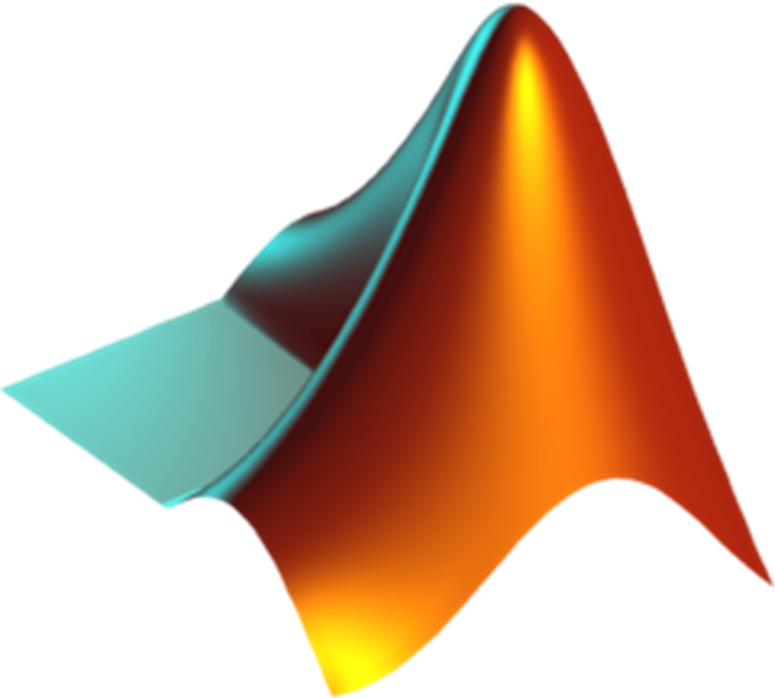

### Declaración de funciones

La definicion de funciones en Python es realizada mediante el conjunto de palabras clave 'function-end'

%Primero declararemos dos numeros
numero1 = 5;
numero2 = 7;

%Posteriormente se realiza el llamado a la funcipon declarada
resultadoSuma = sumaDosNumeros(numero1, numero2);

%Mostraremos el resultado obtenido
disp(['La suma de ' num2str(numero1) ' y ' num2str(numero2) ' es: ' num2str(resultadoSuma)])

La suma de 5 y 7 es: 12


#### Variables Globales

Las variables globales son aquellas que se definen fuera de la función y estan disponibles en todo el programa. Pueden ser accedidas y modificadas descde cualquier funcion o seccion del codigo. se deben utilizar con precaucion para evitar posibles efectos secundarios

global variableGlobal

resultado = funcionConGlobal();
disp(resultado)

    15


disp(variableGlobal)

    10


#### Variables Locales

Las variables locales se definen dentro de una función y solo son accesibles dentro de esa  funcion. Por esta razon no afectan a variables con el mimo nombre fuera de la función

resultado = funcionConLocal();
disp(resultado);

    35



%ESti geberará un error, ya que la variable "variableLocal" no esta
%definida aquí.
%disp(variableLocal)

### Ciclos de programación

#### Ciclo de programación if

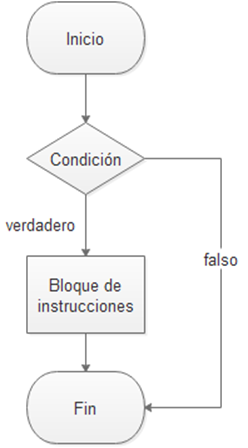

% Solicitar al usuario que ingrese un número
numero = input('Ingresa un número: ')

numero = 2


% Comprobar si el número es positivo, negativo o cero
if numero > 0
    disp('El número es positivo.');
elseif numero < 0
    disp('El número es negativo.');
else
    disp('El número es cero.');
end

El número es positivo.


En este ejercicio, se utiliza la función IF para solicitar al usuario que ingrese un número cualquiera y se determine si su valor es positivo, negativo o cero

**Ciclo if-else**

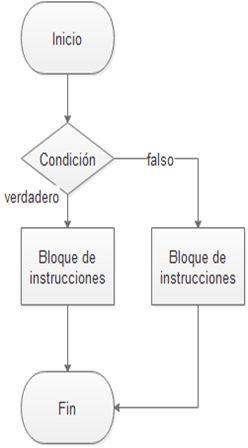

% Solicitar al usuario que ingrese un número
numero = input('Ingresa un número entero: ');

% Comprobar si el número es par o impar
if rem(numero, 2) == 0
    disp('El número ingresado es par.');
else
    disp('El número ingresado es impar.');
end

El número ingresado es impar.


En este ejemplo del uso del ciclo IF-ELSE, se utiliza nuevamente la función input para solicitar un numero al usuario, este valor es usado para identificar si el numero es divisible entre 2 o no

#### Ciclo de programación for

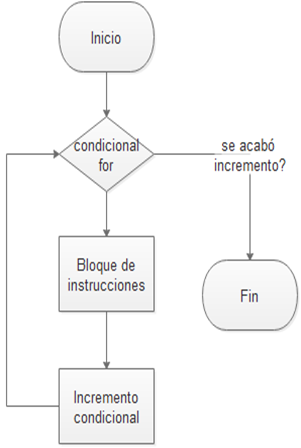

fprintf('Hola, este es un programa para llenar una base de datos \n')

Hola, este es un programa para llenar una base de datos 


n=input('Cuantos datos cargaras: \n');
a = cell(n, 1);
b = zeros(n, 1);

for i=1:n
    aux=string(input('Cual es el nombre ','s'));
    a{i}=aux;
    b(i)=input('Cual es su edad ');
end
for i=1:n
    fprintf('\n El nombre es: %s \n',a{i})
    fprintf('y su edad es: %f',b(i))
end


 El nombre es: juan 


y su edad es: 32.000000

Este código solicita al usuario cuantos datos pretende ingresar, para que a partir de estos llene una BD que tiene un nombre y edad de los datos señalados

#### Ciclo de programación switch

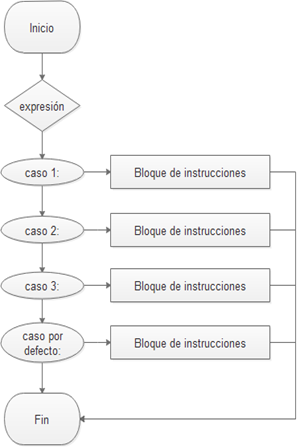

% Solicitar al usuario que ingrese un número de día
numeroDia = input('Ingresa un número de día (1-7): ');

% Evaluar el número de día con un switch
switch numeroDia
    case 1
        nombreDia = 'Lunes';
    case 2
        nombreDia = 'Martes';
    case 3
        nombreDia = 'Miércoles';
    case 4
        nombreDia = 'Jueves';
    case 5
        nombreDia = 'Viernes';
    case 6
        nombreDia = 'Sábado';
    case 7
        nombreDia = 'Domingo';
    otherwise
        nombreDia = 'Número de día no válido';
end

% Mostrar el resultado
fprintf('El número %d corresponde a %s.\n', numeroDia, nombreDia);

El número 3 corresponde a Miércoles.


En este ejemplo se utiliza la función input para solicitar al usuario que ingrese un numero entre 1 a 7. Este valor será utilizado para realizar la funcion de un ciclo switch, que en este caso asignara el nombre correspondiente al dia de la semana. Finalmente el bloque "otherwise" maneja los valores en los que el numero de dia señalado no es valido

#### Ciclo de programación while

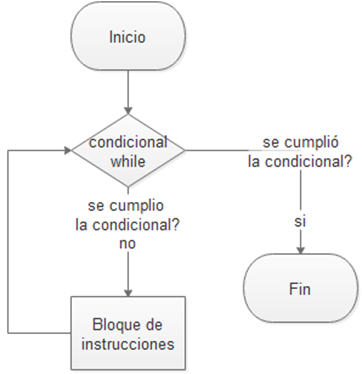

% Generar un número aleatorio entre 1 y 10
numeroSecreto = randi([1, 10]);

% Inicializar la variable de intentos
intentos = 0;

% Pedir al usuario que adivine el número
adivinanza = 0;

while adivinanza ~= numeroSecreto
    adivinanza = input('Adivina el número (entre 1 y 10): ');
    
    % Incrementar el contador de intentos
    intentos = intentos + 1;
    
    % Verificar si la adivinanza es correcta
    if adivinanza == numeroSecreto
        disp('¡Correcto! Has adivinado el número.');
    else
        disp('Incorrecto. Inténtalo de nuevo.');
    end
end

¡Correcto! Has adivinado el número.



% Mostrar el número de intentos
fprintf('Número de intentos: %d\n', intentos);

Número de intentos: 1


En este ejemplo se genera un numero aleatorio entre 1 y 10 (funcion randi([valIni valFin])).  Posteriormente se ejecuta el ciclo while que se ejecutará mientras no se adivine el número exacto 

Además de esto, podemos señalar que existen algunas funciones que puedes colocar dentro de cada ciclo en caso de que quieras realizar acciones predeterminadas dentro del programa

•La sentencia **break **permite abandonar o salirse del lazo generado por las instrucciones *for* o *while*

•La sentencia **return **termina la secuencia actual de comandos y retorna el control a la función que invoco

•La sentencia **continue, **temporalmente interrumpe la ejecución del lazo del programa. A diferencia de *break* y *return* no causa una inmediata salida del lazo de control ya que permanece ahí suspendiendo la ejecución del programa hasta que condición de salida del lazo del programa sea falsa

### ***Continuación de la sección "funciones"***

*Debes de saber que una vez que declaras una función, esta deberá ser colocada al final del archivo y no podrás agregar mas código ejecutable posterior a estas*

**Función ejercicio 1*

function resultado = sumaDosNumeros(a, b)
    %Esta función suma dos números
    resultado = a+b;
end 

**Funcion ejercicio 2*

function resultado = funcionConGlobal()
    global variableGlobal
    resultado = variableGlobal + 5;
end

**Funcion ejercicio 3*

function resultado = funcionConLocal()
    variableLocal = 10;
    resultado = variableLocal + 25;
end